# Mathematical functions

In this section we will take a look at mathematical functions and how to use those.

There are different possibilities to declare and use mathematical functions. For simplification we will just take a look at one specific method. This method is called **anonymous functions.**

**Example**:

% together

The data type of sqr is called function_handle. Where the @ creates the handle and the variables inside the function are the arguments of the function. 

In the End it basically behaves like a regular function (which is the most interesting/important part for us)

ans = 9

x =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


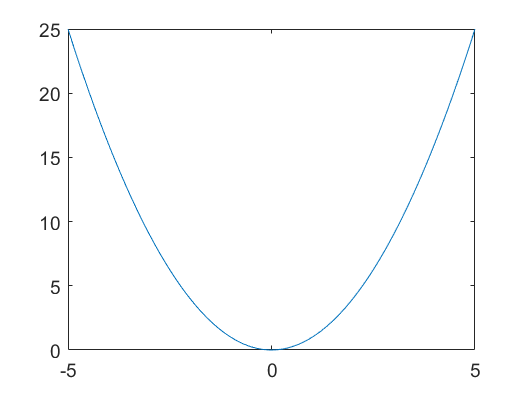

% together

we can also use more different variables

**Example**:

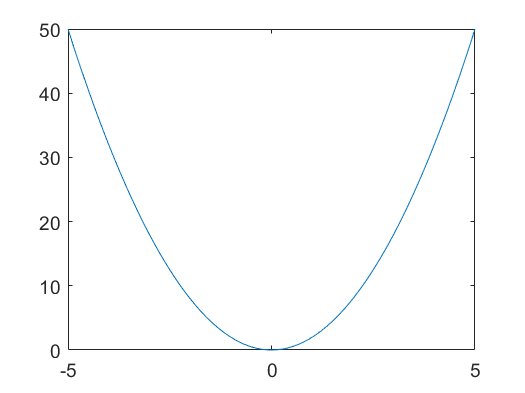

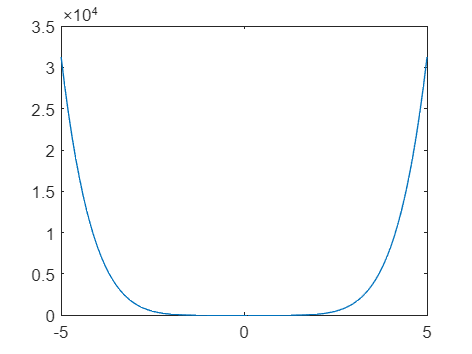

% together

better way of doing it:

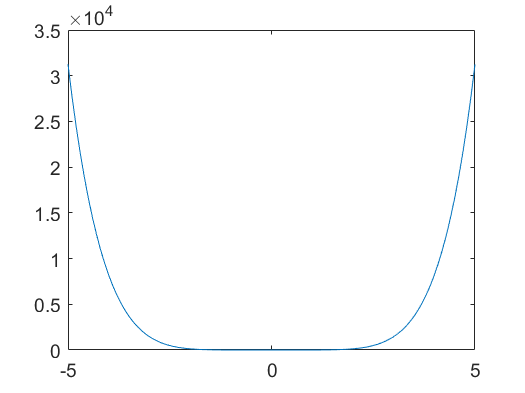

% together

**Exercise**: Think of your own function with at least 3 constants as input. 

funExample = function_handle with value:
    @(x,xdata)x(1).*(xdata-x(2)).^2+x(3)



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x1 =    -1.0000    4.0000    5.0000


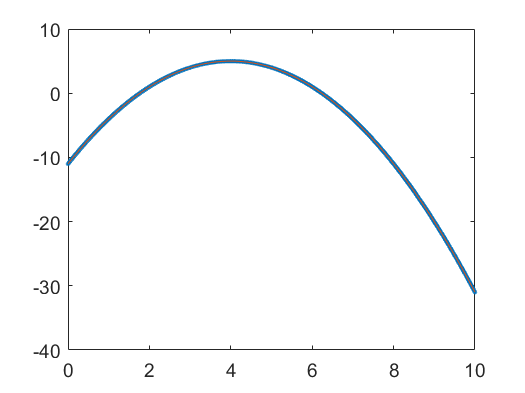

% your code

## Section: Fitting

**Little excurse exercise: **Create an extra Matlab file and import the data from the exercise before and run it.

- (Together) Lets have a look at the PLOTS application of Matlab

- (Together) Lets also have a look at the Figure Palette

- Installation of the curve fitting toolbox

- Using the curve fitting toolbox

**Exercise:**

create a new .m file for the next points:

- load weirdPoly.csv to workspace and open it with curve fitting toolbox; try to fit it with polynomial fit

- load sinCurvefit.csv => try to fit it with sine => you will notice that it doesn´t work as you planned => There for: create your own custom function a*sin(b*x) + c

- load sinc.csv => google for sinc-function and try to fit it (you don´t need to understand the function)

**New**: First fit method `x = lsqcurvefit(fun,x0,xdata,ydata) `this method solves nonlinear equation with a least square algorithm

Link: [Solve nonlinear curve-fitting (data-fitting) problems in least-squares sense - MATLAB lsqcurvefit - MathWorks Deutschland](https://de.mathworks.com/help/optim/ug/lsqcurvefit.html)

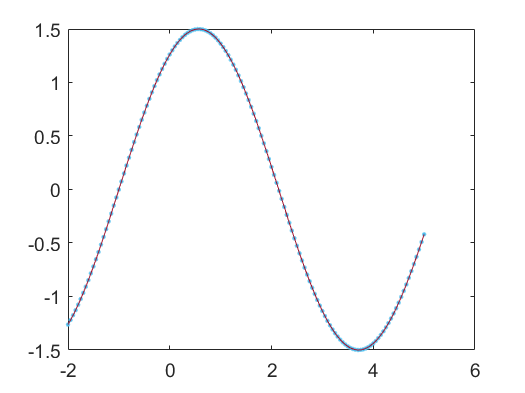

fun = function_handle with value:
    @(x,xdata)x(1).*sin(xdata+x(2))



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x =     1.5000    1.0000


% together

**Exercise**: (hint: stick closely with the example above)

- import the sin.csv and plot it

- build your own fit function: y = a * sin(x + b)

- use lsqcurvefit() to find the parameters

- plot the data

% your code

funCrossing = function_handle with value:
    @(z)fun(x,z)


zerosCrossings = -1.0000

maxima = 1.4997

maxInd = 52

ans = 0.5500

minima = -1.4999

minInd = 115

ans = 3.7000

integral2 = -0.6297

%  f(x) = a.*sin(xdata + b)


**New:** Find zero with **fzero**() function. With the help of this function, we can find all zero crossings. 

**Link: **[Root of nonlinear function - MATLAB fzero - MathWorks Deutschland](https://de.mathworks.com/help/matlab/ref/fzero.html)

% together

**Exercise**: 

- Do the same thing with the data of the sin (sin.csv) and find **all** zero crossings. 

- Find the Maximum and the Minimum as well as their indices (and the corresponding x-values)

- **Advanced**: Use the trapz()-function and integral()-function to determine the area bellow the sin function.

% your code